## QS1

### part1


$$G(s)=\frac{100(s+2)}{s(s+5)(s+10)}$$
 

tf1_open=tf([100,200],[1,15,50,0])

tf1_open =
 
      100 s + 200
  -------------------
  s^3 + 15 s^2 + 50 s
 
Continuous-time transfer function.



closed loop transfer function


$$\frac{G(s)}{1+G(s)}=\frac{100(s+2)}{s(s+5)(s+10)+100(s+2)}$$
 

#### a) Bode plot

%Transfer function:
tf1=tf([100,200],[1,15,150,200])

tf1 =
 
         100 s + 200
  --------------------------
  s^3 + 15 s^2 + 150 s + 200
 
Continuous-time transfer function.



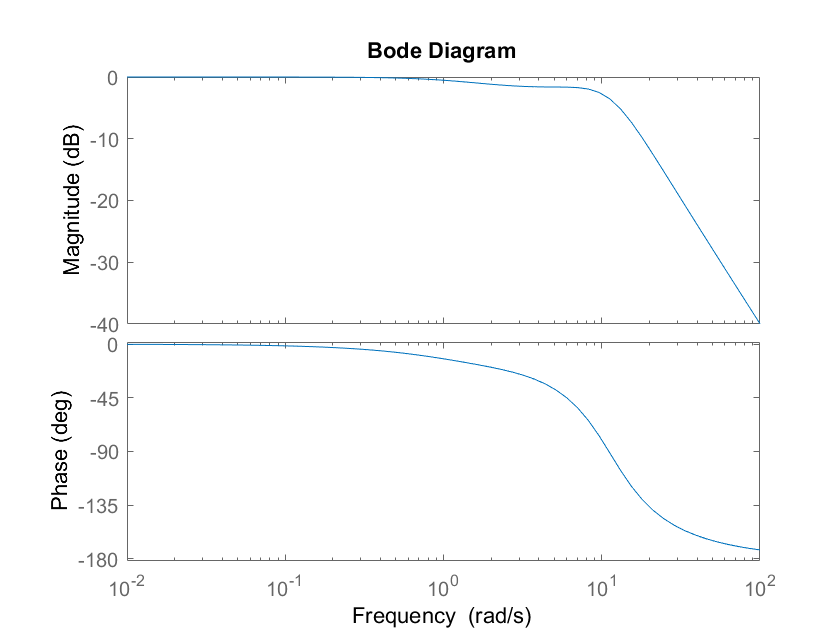

w1=0.01;
w2=100;
bode(tf1,{w1,w2})

#### **b)** Gain margin, Phase margin, Phase crossover frequency, Gain crossover frequency:-

allmargin(tf1) 

ans = struct with fields:
     GainMargin: Inf
    GMFrequency: Inf
    PhaseMargin: -180
    PMFrequency: 0
    DelayMargin: Inf
    DMFrequency: 0
         Stable: 1


#### **c)** resonant peak, resonance frequency and bandwidth:-

[gpeak1,fpeak1]=getPeakGain(tf1) %closed loop property

gpeak1 = 1.0000

fpeak1 = 0

bw1=bandwidth(tf1)

bw1 = 10.4767

### **part2**


$$G(s)=\frac{20(s+1)}{s(s+5)(s^2+2s+10)}$$
 

closed loop transfer function


$$\frac{G(s)}{1+G(s)}=\frac{20(s+1)}{s(s+5)(s^2+2s+10)+20(s+1)}$$
 

#### a) Bode plot

%Transfer function:
tf2=tf([20,20],[1,7,20,70,20])

tf2 =
 
             20 s + 20
  --------------------------------
  s^4 + 7 s^3 + 20 s^2 + 70 s + 20
 
Continuous-time transfer function.



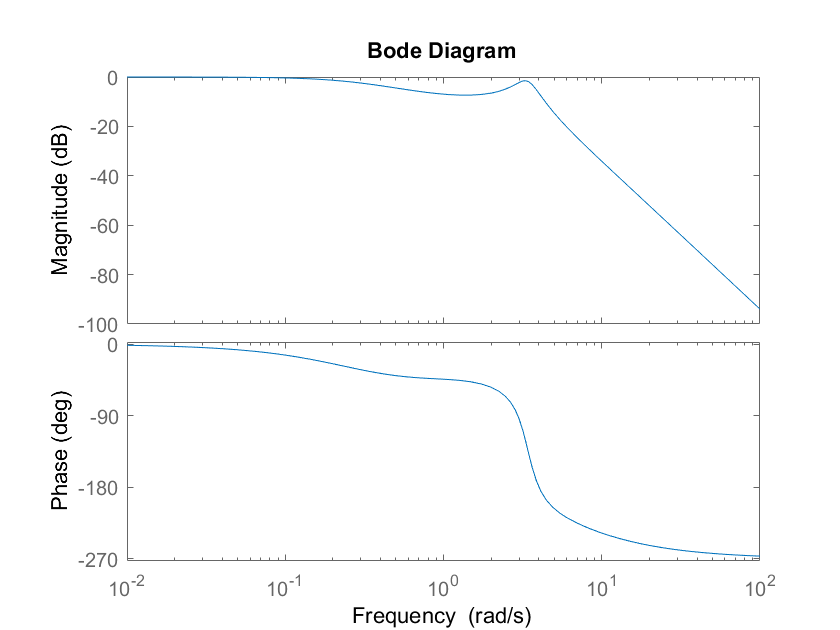

bode(tf2,{w1,w2})

#### **b)** Gain margin, Phase margin, Phase crossover frequency, Gain crossover frequency:-

allmargin(tf2)

ans = struct with fields:
     GainMargin: 2.1393
    GMFrequency: 4.0142
    PhaseMargin: -180
    PMFrequency: 0
    DelayMargin: Inf
    DMFrequency: 0
         Stable: 1


#### **c)** resonant peak, resonance frequency and bandwidth:-

[gpeak2,fpeak2]=getPeakGain(tf2)

gpeak2 = 1

fpeak2 = 0

bw2=bandwidth(tf2)

bw2 = 0.3508

### **part3**


$$G(s)=\frac{10(s^2+0.4s+1)}{s(s^2+0.8s+9)}$$


closed loop transfer function


$$\frac{G(s)}{1+G(s)}=\frac{10(s^2+0.4s+1)}{s(s^2+0.8s+9)+10(s^2+0.4s+1)}$$
 

#### **a)** Bode plot:-

%Transfer function:
tf3=tf([10,4,10],[1,10.8,13,10])

tf3 =
 
      10 s^2 + 4 s + 10
  --------------------------
  s^3 + 10.8 s^2 + 13 s + 10
 
Continuous-time transfer function.



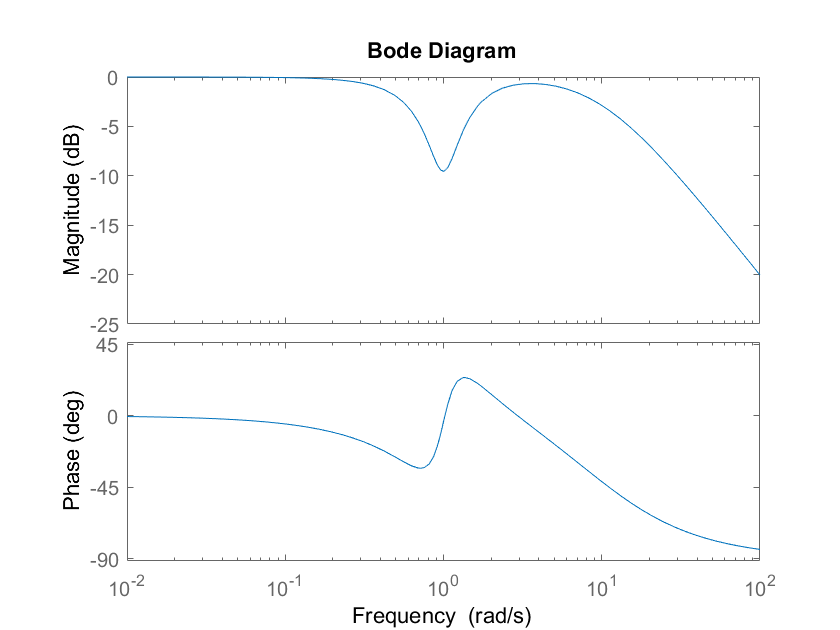

bode(tf3,{0.01,100})

#### **b)** Gain margin, Phase margin, Phase crossover frequency, Gain crossover frequency:-

allmargin(tf3)

ans = struct with fields:
     GainMargin: [1×0 double]
    GMFrequency: [1×0 double]
    PhaseMargin: -180
    PMFrequency: 0
    DelayMargin: Inf
    DMFrequency: 0
         Stable: 1


#### **c)** resonant peak, resonance frequency and bandwidth:-

[gpeak3,fpeak3]=getPeakGain(tf3)

gpeak3 = 1

fpeak3 = 0

bw3=bandwidth(tf3)

bw3 = 0.5943

## **QS2**

open loop $G(s)=\frac{K}{s(s+1)(s+5)}$ 

closed loop transfer function


$$\frac{G(s)}{1+G(s)}=\frac{K}{s(s+1)(s+5)+K}$$
 

Transfer functions for K = 10, 20 and 100

H1=tf(10,[1,6,5,10])

H1 =
 
            10
  ----------------------
  s^3 + 6 s^2 + 5 s + 10
 
Continuous-time transfer function.



H2=tf(20,[1,6,5,20])

H2 =
 
            20
  ----------------------
  s^3 + 6 s^2 + 5 s + 20
 
Continuous-time transfer function.



H3=tf(100,[1,6,5,100])

H3 =
 
            100
  -----------------------
  s^3 + 6 s^2 + 5 s + 100
 
Continuous-time transfer function.



#### **a)** Bode plot of closed loop systems:-

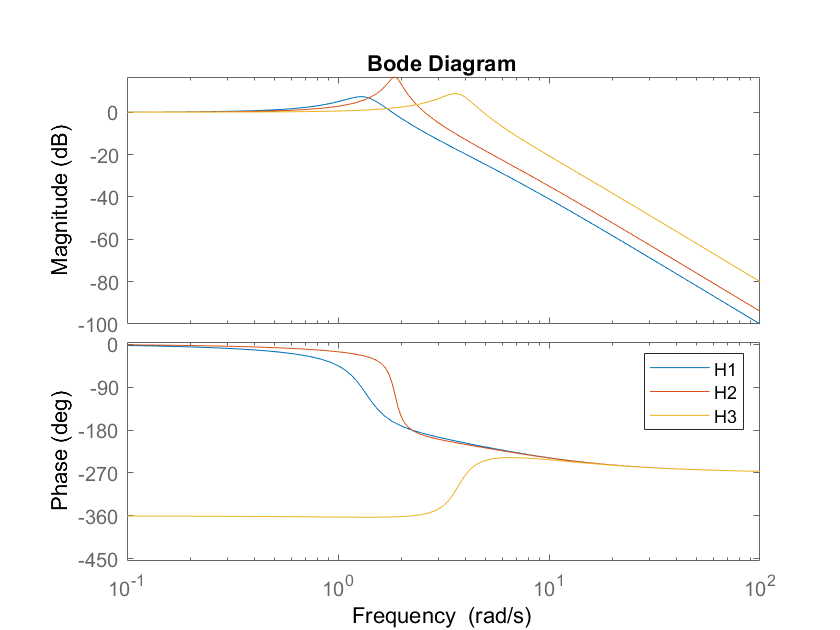

bode(H1,H2,H3)
legend

#### **b)** 

We cannot predict the stability from the frequency response/bode plot of the closed loop system. As we cannot replace s by $j\omega$ in case of K=100 as it is an unstable system which has region of convergence $Re(s)\geq a$ where $a>0$. Hence we find the gain and phase margin of the open loop system for 3 values of K,

H1=tf(10,[1,6,5,0]);
H2=tf(20,[1,6,5,0]);
H3=tf(100,[1,6,5,0]);
%For H1(K=10):
allmargin(H1)

ans = struct with fields:
     GainMargin: 3
    GMFrequency: 2.2361
    PhaseMargin: 25.3898
    PMFrequency: 1.2271
    DelayMargin: 0.3611
    DMFrequency: 1.2271
         Stable: 1


%For H2(K=20):
allmargin(H2)

ans = struct with fields:
     GainMargin: 1.5000
    GMFrequency: 2.2361
    PhaseMargin: 8.9095
    PMFrequency: 1.8147
    DelayMargin: 0.0857
    DMFrequency: 1.8147
         Stable: 1


%For H3(K=100):
allmargin(H3)

ans = struct with fields:
     GainMargin: 0.3000
    GMFrequency: 2.2361
    PhaseMargin: -23.6504
    PMFrequency: 3.9073
    DelayMargin: 1.5024
    DMFrequency: 3.9073
         Stable: 0


thus gain and phase margin for K=10, 20 is +ve and also for those values of K the closed loop system is stable. 

But for K=100, both gain and phase margins are -ve, so the closed loop system is unstable.

#### **c)**  

Minimum value of K for which the system becomes unstable, i.e. the gain margin=0dB and phase margin=$0^\circ$. At phase crossover, imaginary part of the open loop expression should be 0 when we put $j\omega$ in place of s. S0, $\omega^3=5\omega$ and hence, at limiting point, $\omega_{cg}=\omega_{cp}=\sqrt{5}$ and $\frac{K}{-6\omega^2}=-1$ as gain margin=0dB. So minimum value of K for which the system is unstable is K=30.

k=29.9;
H=tf(k,[1,6,5,0]);
allmargin(H)

ans = struct with fields:
     GainMargin: 1.0033
    GMFrequency: 2.2361
    PhaseMargin: 0.0713
    PMFrequency: 2.2323
    DelayMargin: 5.5762e-04
    DMFrequency: 2.2323
         Stable: 1


k=30;
H=tf(k,[1,6,5,0]);
allmargin(H)

ans = struct with fields:
     GainMargin: 1.0000
    GMFrequency: 2.2361
    PhaseMargin: 9.5374e-06
    PMFrequency: 2.2361
    DelayMargin: 7.4443e-08
    DMFrequency: 2.2361
         Stable: 0


After K=30, it has approximately 0 gain and phase margin and same crossover frequencies and closed loop system becomes unstable. At K=30 the closed loop system is marginally stable.

**d)**  

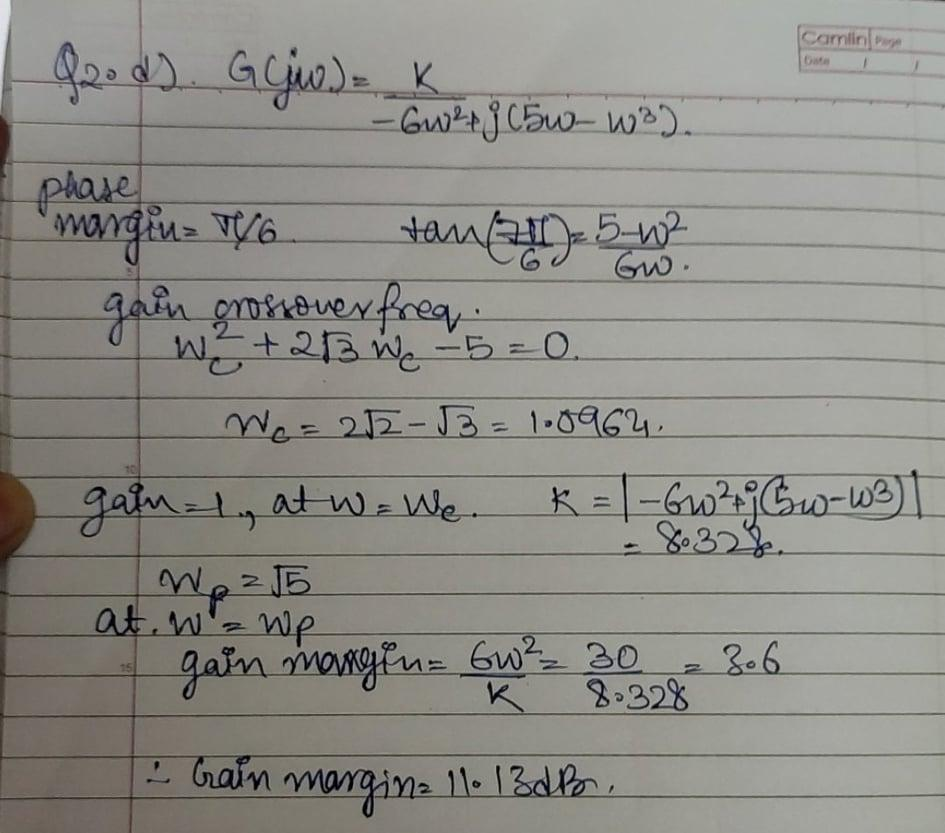

k=8.328;
H=tf(k,[1,6,5,0]);
allmargin(H)

ans = struct with fields:
     GainMargin: 3.6023
    GMFrequency: 2.2361
    PhaseMargin: 30.0000
    PMFrequency: 1.0964
    DelayMargin: 0.4776
    DMFrequency: 1.0964
         Stable: 1


## QS3

#### a,b)

#### 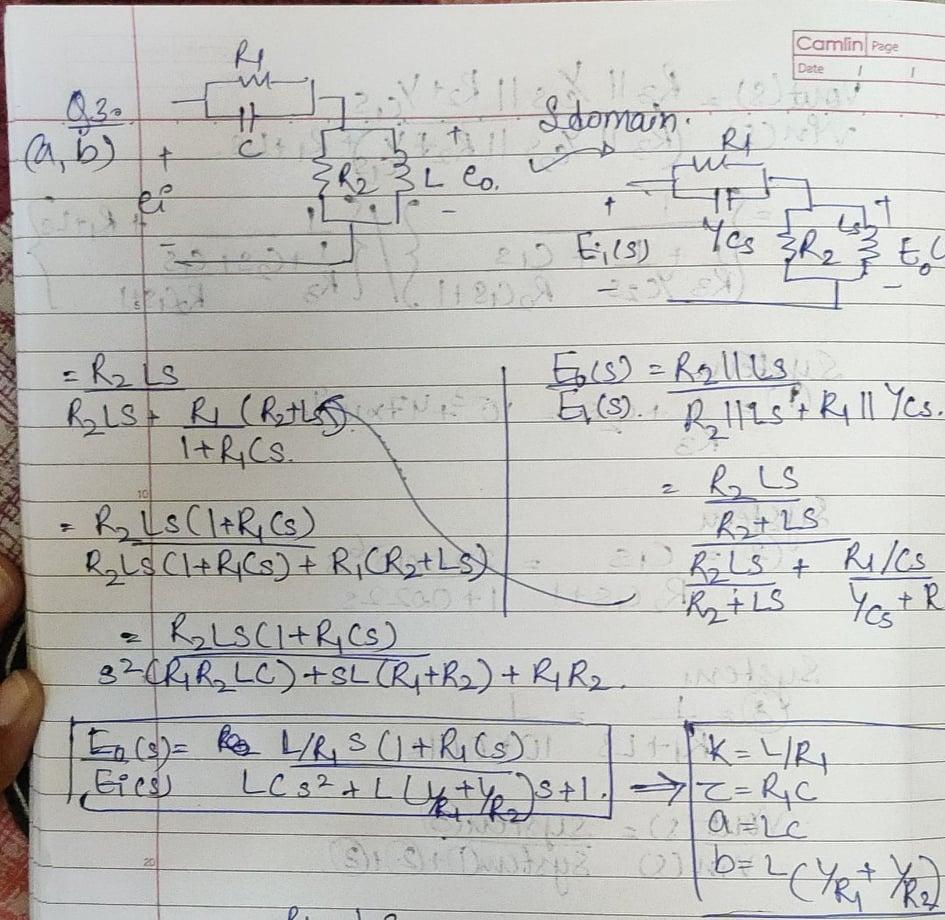

#### **c)**

% these system are defined from the calculations shown at end 

k=1e-5;
t=0.02;
a=2e-7;
b=1.2e-5;
G=tf([k*t,k,0],[a,b,1])

G =
 
     2e-07 s^2 + 1e-05 s
  -------------------------
  2e-07 s^2 + 1.2e-05 s + 1
 
Continuous-time transfer function.



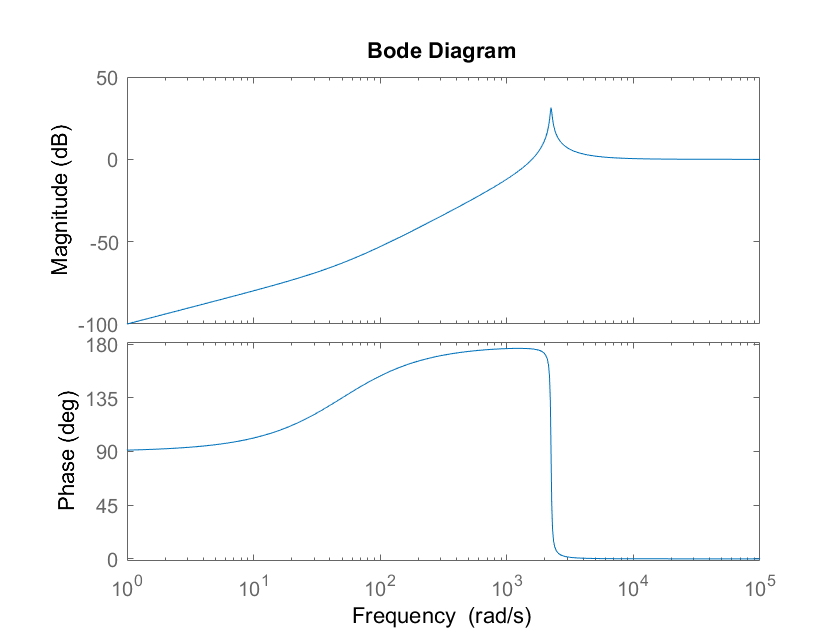

bode(G)

It acts as a high-pass filter. As the phase never crosses $-180^\circ$ so, we cannot calculate gain margin. There is a point before the resonant peak where the gain = 1.

allmargin(G)

ans = struct with fields:
     GainMargin: [1×0 double]
    GMFrequency: [1×0 double]
    PhaseMargin: [-3.9847 -180]
    PMFrequency: [1.5812e+03 Inf]
    DelayMargin: [0.0039 0]
    DMFrequency: [1.5812e+03 Inf]
         Stable: 1


So at (crossover frequency)$\omega=1.58\times10^3$, the gain = 1, and the phase margin is equal to $-3.98^\circ$.

## QS4

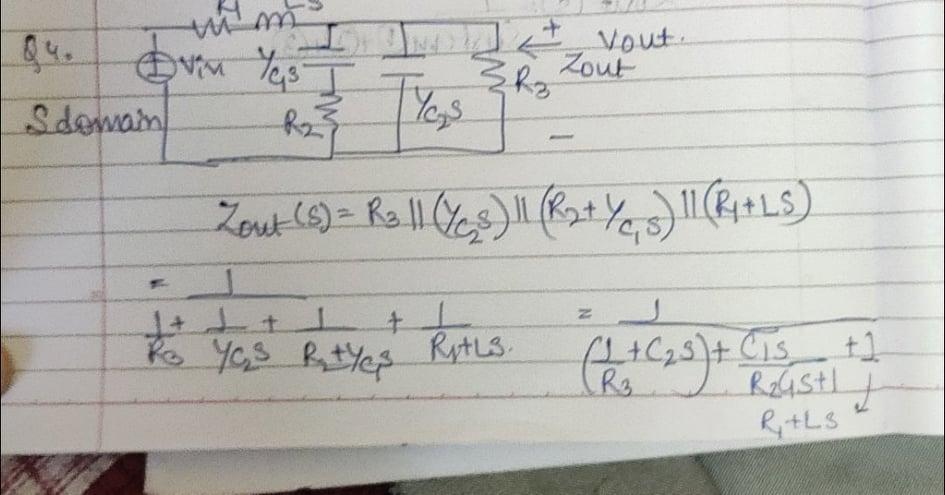

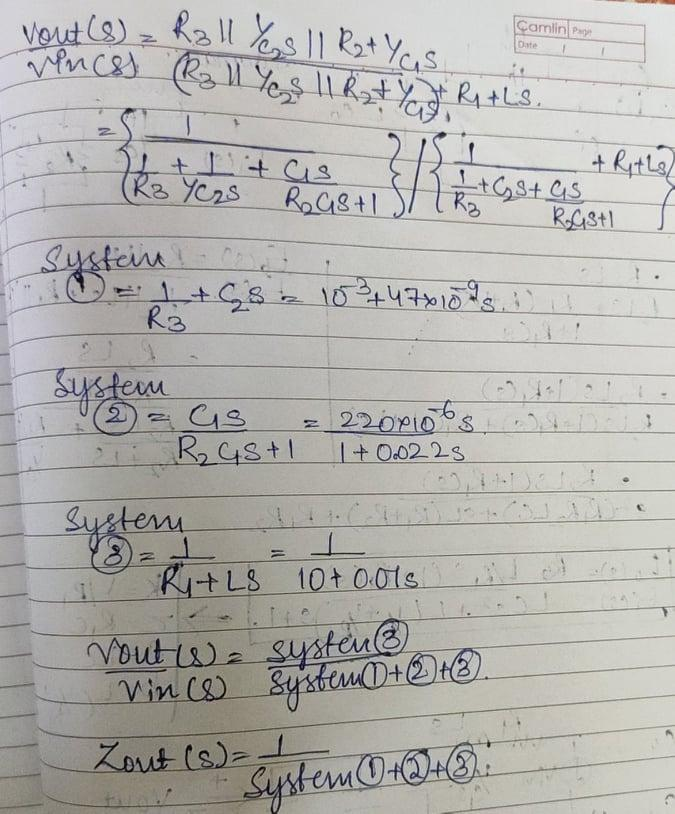

% these system are defined from the calculations shown at end 

sys1=tf([47e-9,1e-3],1);
sys2=tf([220e-6,0],[0.022,1]);
sys3=tf(1,[0.01,10]);
Zout=1/(sys1+sys2+sys3)
H=sys3/(sys1+sys2+sys3) %Vo/Vin
bode(Zout)
legend
bode(H)
legend % low-pass filter.
bandwidth(H)

Hence corner frequency of the low-pass filter(-3dB frequency) = **8524.1 rad/sec **= **1.357KHz**

## **QS5**